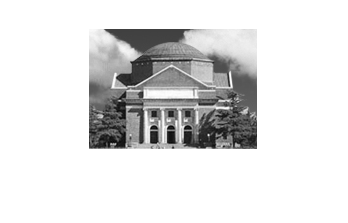

clear
clc

load('hall.mat');
imshow(hall_gray); % original image

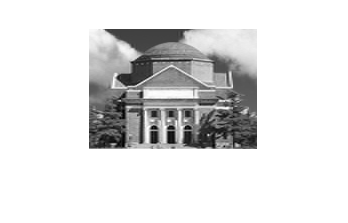

hall_gray = double(hall_gray) - 128;
hall_gray_lp = blockproc(hall_gray,[8 8],@(mat)(DCTlp(mat.data)+128));
hall_gray_hp = blockproc(hall_gray,[8 8],@(mat)(DCThp(mat.data)+128));
imshow(uint8(hall_gray_lp));

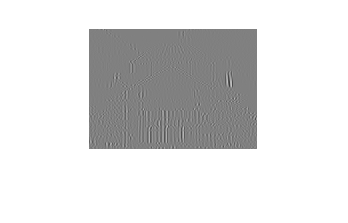

imshow(uint8(hall_gray_hp));

function rslt = DCTlp(mat)
    rslt = dct2(mat);
    rslt(:,end-3:end) = 0;
    rslt = idct2(rslt);
end

function rslt = DCThp(mat)
    rslt = dct2(mat);
    rslt(:,1:4) = 0;
    rslt = idct2(rslt);
end